## Visualización de Datos

Creemos los datos que nos servirán para realizar los ejemplos y guardémoslo en un archivo:

matrizDatos=randi(100, 100);
save ../data/matrizDatos matrizDatos

Creemos los datos que nos servirán para realizar los ejemplos:

A = struct2mat(load("../data/matrizDatos"))

A =     44    44    10    32     7    99    83    92    16    37    80    21    46     8    59    79    23    49    52    53    62     6    10    52     2    62    80    86    87    92     1    84    87    23    90    21    44    74    16    22     4     7    69    39    70    46     8    39    57    68
    17    69    82    58     4    78    15    92    99    33    56    89    93    76    26     8    22    52    59    52    85    94    46    81    28     2    52    23    43    82    58    61    46    20    33    27    73    37    14    94    38    40    91    54    42    40    97    68    15    69
    78     1    15    87    78    97     7    50     6    57    29    23    23    43    43    40    86    87    96    67    21    15    44    16    95    29     5    73    20    44    55    25    97    28    79    67    30    50    87    82    21    63    33    59    99    63    71    44    55    79
    23    37    57     5    23    64    74     8    80    23    24    72    80    46    92   

B=flipud(A);
C=fliplr(A);
D=rot90(A);
E=A';
F=A(:);

Ahora creemos nuestra primera gráfica utilizando la función `imgesc(A)`: esta muestra los datos del arreglo A como una imagen que usa la gama completa de colores del mapa de colores. Cada elemento de A especifica el color de un píxel de la imagen. La imagen resultante es una cuadrícula de píxeles de `m` por `n` donde `m` es el número de filas y `n` es el número de columnas de A. Los índices de fila y de columna de los elementos determinan los centros de los píxeles correspondientes. Veamos un ejemplo:

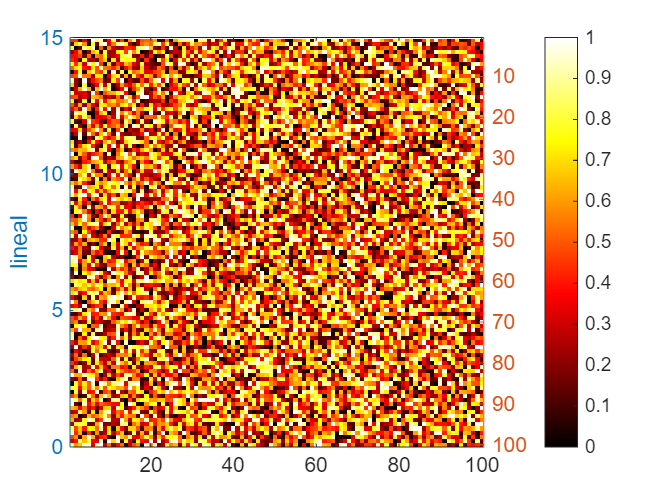

imagesc(A); clim([0 100]); colormap hot; colorbar

 Distintas escalas de `colormap` se pueden encontrar en este [enlace](https://la.mathworks.com/help/matlab/ref/colormap.html?s_tid=doc_ta). Ahora usemos el comando `subplot(m,n,p)`: divide la figura actual en una cuadrícula de `m` por `n` y crea ejes en la posición que especifica `p`. MATLAB® numera las posiciones de subgráfica por fila. La primera subgráfica es  la primera columna de la primera fila, la segunda subgráfica es la  segunda columna de la primera fila y así sucesivamente. Si hay ejes en  la posición especificada, este comando convierte los ejes en los ejes  actuales.

figure % crea una ventana de figura nueva utilizando valores de propiedades predeterminados.
subplot(2,3,1)
imagesc(A); clim([0 50]); colormap jet; colorbar
title('matriz A')
ylabel('valor en y')

Agreguemos otra figura:

subplot(2,3,2)
imagesc(B); clim([0 100]); colormap jet; colorbar
title('flipud(A)')

Y adjuntemos algunas más:

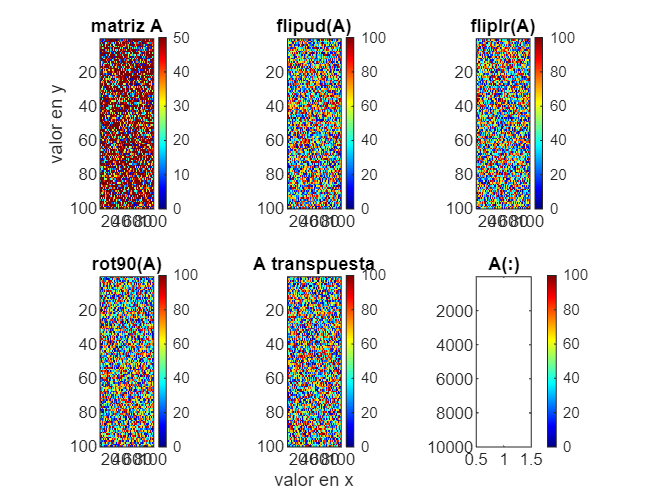

subplot(2,3,3)
imagesc(C); caxis([0 100]); colormap jet; colorbar
title('fliplr(A)')
subplot(2,3,4)
imagesc(D); caxis([0 100]); colormap jet; colorbar
title('rot90(A)')
subplot(2,3,5)
imagesc(E); caxis([0 100]); colormap jet; colorbar
title('A transpuesta')
xlabel('valor en x')
subplot(2,3,6)
imagesc(F); caxis([0 100]); colormap jet; colorbar
title('A(:)')

Con la función `pcolor(A)` se puede crear otro tipo de gráfica: crea un gráfico de pseudocolores utilizando los valores de la matriz C. Un gráfico de pseudocolores muestra los datos de la matriz como un arreglo de celdas coloreadas (conocidas como caras).

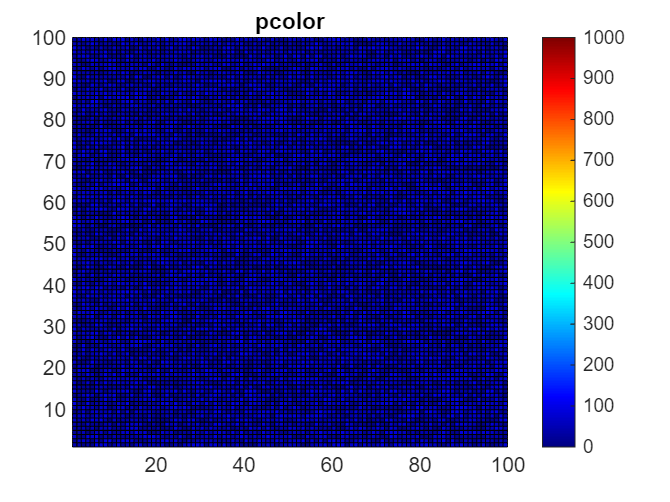

figure
pcolor(A); clim([0 1000]); colormap jet; colorbar
title('pcolor')
shading flat
shading faceted

Generar una figra 2D con `plot(X,Y)`.  Primero creemos los datos para los ejemplos:

X=0:0.01:30; b=1;
Y=0.45*X+b;
Y2=3.*sin(2*pi/3*X);
Y3=Y2.*exp(0.5*X);

Grafiquemos lo siguientes:

figure
plot(X,Y,'-')
hold on

Agreguemos la siguiente gráfica:

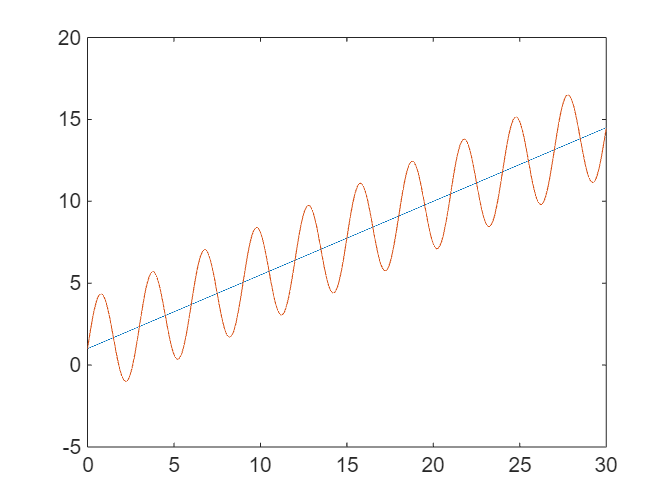

plot(X,Y2+Y)

Veamos otro ejemplo:

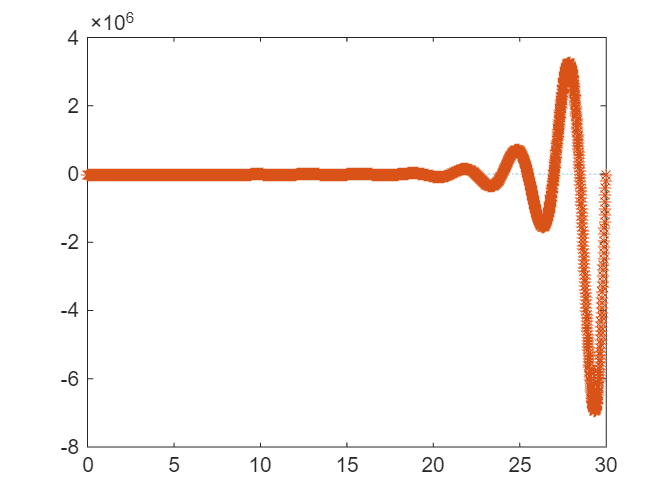

figure
plot(X,Y,'--',X,Y3,'*')

Exploremos otras opciones que podemos usar con la función `plot`:

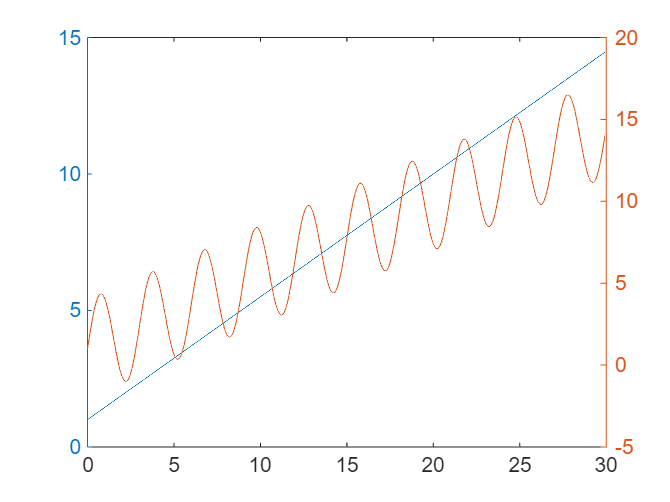

figure
yyaxis left
plot(X,Y)
yyaxis right
plot(X,Y2+Y)

Analicemos este ejemplo:

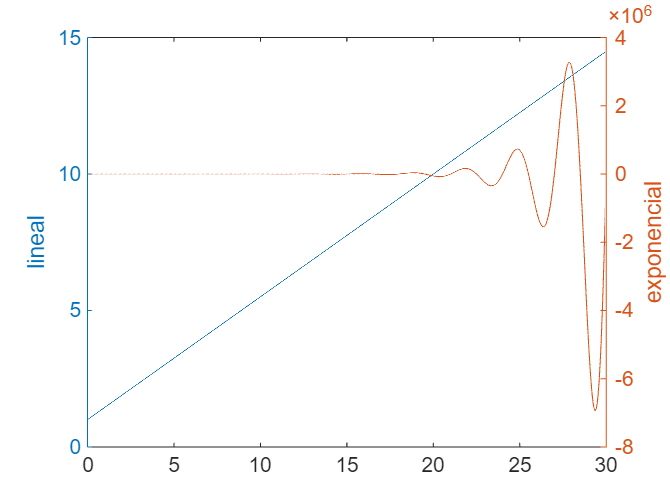

figure
yyaxis left
plot(X,Y)
ylabel('lineal')
yyaxis right
plot(X,Y3)
ylabel('exponencial')